clc
clear all
format long


%%%%%%Variable declaration%%%%%%%%%%%%
%-------------------------------------------%
F_f=0.5:0.01:1.5 %non-dimensional forcing frequency

F_f =    0.500000000000000   0.510000000000000   0.520000000000000   0.530000000000000   0.540000000000000   0.550000000000000   0.560000000000000   0.570000000000000   0.580000000000000   0.590000000000000   0.600000000000000   0.610000000000000   0.620000000000000   0.630000000000000   0.640000000000000   0.650000000000000   0.660000000000000   0.670000000000000   0.680000000000000   0.690000000000000   0.700000000000000   0.710000000000000   0.720000000000000   0.730000000000000   0.740000000000000   0.750000000000000   0.760000000000000   0.770000000000000   0.780000000000000   0.790000000000000   0.800000000000000   0.810000000000000   0.820000000000000   0.830000000000000   0.840000000000000   0.850000000000000   0.860000000000000   0.870000000000000   0.880000000000000   0.890000000000000   0.900000000000000   0.910000000000000   0.920000000000000   0.930000000000000   0.940000000000000   0.950000000000000   0.960000000000000   0.970000000000000   0.980000000000000   0.990000000

A=0.1; % non-dimensional forcing amplitude
omega_mat=2*pi*F_f %circular frequency

omega_mat =    3.141592653589793   3.204424506661589   3.267256359733385   3.330088212805181   3.392920065876977   3.455751918948773   3.518583772020569   3.581415625092364   3.644247478164160   3.707079331235956   3.769911184307752   3.832743037379548   3.895574890451344   3.958406743523139   4.021238596594936   4.084070449666731   4.146902302738527   4.209734155810323   4.272566008882118   4.335397861953914   4.398229715025710   4.461061568097506   4.523893421169302   4.586725274241098   4.649557127312894   4.712388980384690   4.775220833456485   4.838052686528282   4.900884539600077   4.963716392671873   5.026548245743669   5.089380098815465   5.152211951887261   5.215043804959057   5.277875658030853   5.340707511102649   5.403539364174444   5.466371217246240   5.529203070318036   5.592034923389832   5.654866776461628   5.717698629533424   5.780530482605219   5.843362335677015   5.906194188748811   5.969026041820607   6.031857894892402   6.094689747964199   6.157521601035994   6.220

phi=0; %initial phase
t1=0; % initial time
t_run=40; %final time


dt=1e-5; %time step
num_vor=100; %number of vortices shed;

for omega = omega_mat
    for j=1:num_vor
        
        tm=(t1):dt:(t1+t_run);
        for i=1:length(tm)
            tt=tm(i+1)-t1; 
            gam(i)=tt*(A^2/4+1/2)-A^2*(sin(2*omega*tm(i+1)+2*phi)-sin(2*omega*t1+2*phi))/(8*omega)+...
                A*(cos(omega*t1+phi)-cos(omega*tm(i+1)+phi))/omega; %Gamma_m
            gam_c(i)=0.5*(1+A*sin(omega*tm(i+1)+phi)); %threshold circulation Gamma_sep
            
            if gam(i)>=gam_c(i)
                gam(i+1)=0;
                tf(j)=tt; %Shedding time period
                break
            end
        end
        
        clear gam gam_c
        t1=tm(i+1);  %t1=t2 condition 
        j;
    end
    p = (omega/(2*pi))*ones(1, length(tf(50:end)));
    omega/(2*pi)
    %if (omega/(2*pi)) == tf(end)
     %   plot(p(end), 1./tf(end),"ro",'MarkerSize',4)
      %  disp("ha")
    %else
    plot(p, 1./tf(50:end), "color",'#A2142F', "Marker",".", "MarkerSize", 20)
    %end
    hold on
    clear p
end

ans =    0.500000000000000


ans =    0.510000000000000


ans =    0.520000000000000


ans =    0.530000000000000


ans =    0.540000000000000


ans =    0.550000000000000


ans =    0.560000000000000


ans =    0.570000000000000


ans =    0.580000000000000


ans =    0.590000000000000


ans =    0.600000000000000


ans =    0.610000000000000


ans =    0.620000000000000


ans =    0.630000000000000


ans =    0.640000000000000


ans =    0.650000000000000


ans =    0.660000000000000


ans =    0.670000000000000


ans =    0.680000000000000


ans =    0.690000000000000


ans =    0.700000000000000


ans =    0.710000000000000


ans =    0.720000000000000


ans =    0.730000000000000


ans =    0.740000000000000


ans =    0.750000000000000


ans =    0.760000000000000


ans =    0.770000000000000


ans =    0.780000000000000


ans =    0.790000000000000


ans =    0.800000000000000


ans =    0.810000000000000


ans =    0.820000000000000


ans =    0.830000000000000


ans =    0.840000000000000


ans =    0.850000000000000


ans =    0.860000000000000


ans =    0.870000000000000


ans =    0.880000000000000


ans =    0.890000000000000


ans =    0.900000000000000


ans =    0.910000000000000


ans =    0.920000000000000


ans =    0.930000000000000


ans =    0.940000000000000


ans =    0.950000000000000


ans =    0.960000000000000


ans =    0.970000000000000


ans =    0.980000000000000


ans =    0.990000000000000


ans =      1


ans =    1.010000000000000


ans =    1.020000000000000


ans =    1.030000000000000


ans =    1.040000000000000


ans =    1.050000000000000


ans =    1.060000000000000


ans =    1.070000000000000


ans =    1.080000000000000


ans =    1.090000000000000


ans =    1.100000000000000


ans =    1.110000000000000


ans =    1.120000000000000


ans =    1.130000000000000


ans =    1.140000000000000


ans =    1.150000000000000


ans =    1.160000000000000


ans =    1.170000000000000


ans =    1.180000000000000


ans =    1.190000000000000


ans =    1.200000000000000


ans =    1.210000000000000


ans =    1.220000000000000


ans =    1.230000000000000


ans =    1.240000000000000


ans =    1.250000000000000


ans =    1.260000000000000


ans =    1.270000000000000


ans =    1.280000000000000


ans =    1.290000000000000


ans =    1.300000000000000


ans =    1.310000000000000


ans =    1.320000000000000


ans =    1.330000000000000


ans =    1.340000000000000


ans =    1.350000000000000


ans =    1.360000000000000


ans =    1.370000000000000


ans =    1.380000000000000


ans =    1.390000000000000


ans =    1.400000000000000


ans =    1.410000000000000


ans =    1.420000000000000


ans =    1.430000000000000


ans =    1.440000000000000


ans =    1.450000000000000


ans =    1.460000000000000


ans =    1.470000000000000


ans =    1.480000000000000


ans =    1.490000000000000


ans =    1.500000000000000


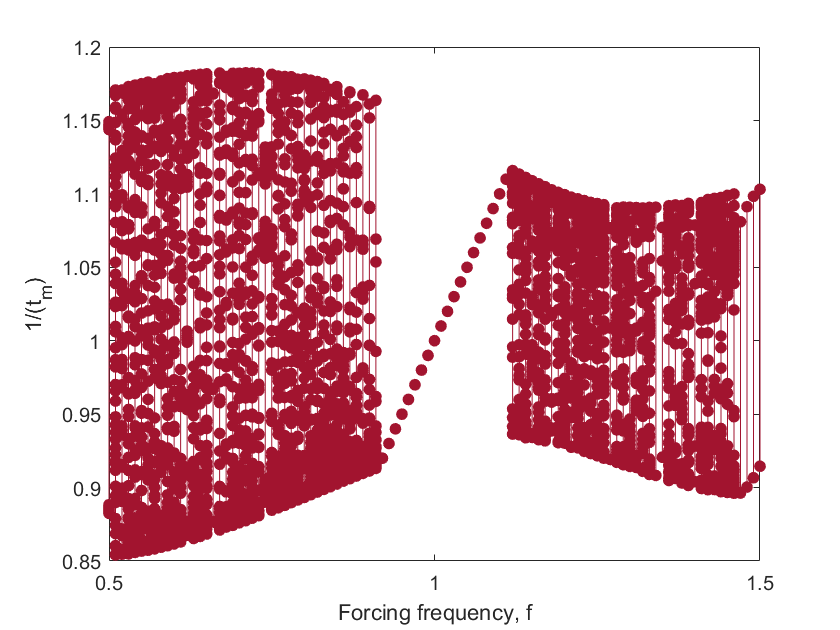

hold off
xlabel("Forcing frequency, f")
ylabel("1/(t_m)")